dataDir = 'datasets';
addpath('../');

## RNN-DBSCAN clustering tests

The original author's did not release their code, so these tests are for me to see if my implementation is correct, or at least performs reasonably.

SPDX-License-Identifier: BSD-3-Clause

## Tests on datasets used in their paper

They report performance on some shape-based synthetic datasets (Table 3). I am going to attempt to repeat their results on these datasets:

- aggregation

- d31

- flame

- jain

- r15

- spiral

- pathbased

These datasets are from the [University of Finland shape sets](http://cs.uef.fi/sipu/datasets/). Some of them are directly from that site, and some are from this [Github repo](https://github.com/milaan9/Clustering-Datasets) that converted the datasets into mat files. 

In the paper, they report the Adjusted Rand Index (ari), purity, # of clusters, and # of noise points. I am just going to compare ari, # of clusters, and # of noise points.

They sweep k from 1 to 100 and find the k that results in the max ARI, so I will do the same.

`rand_index` is by Chris McComb on [GitHub](https://github.com/cmccomb/rand_index); it needs to be on the MATLAB path

### Aggregation

#### original labels

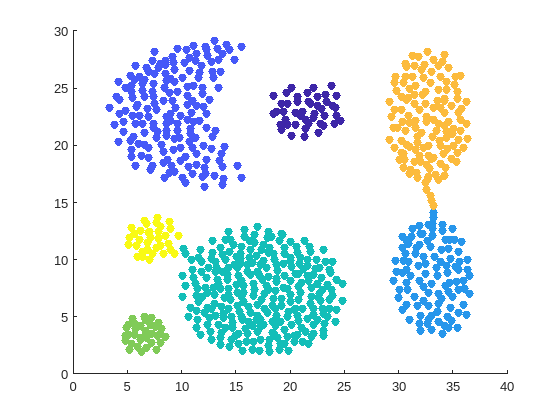

load([dataDir filesep 'aggregation.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

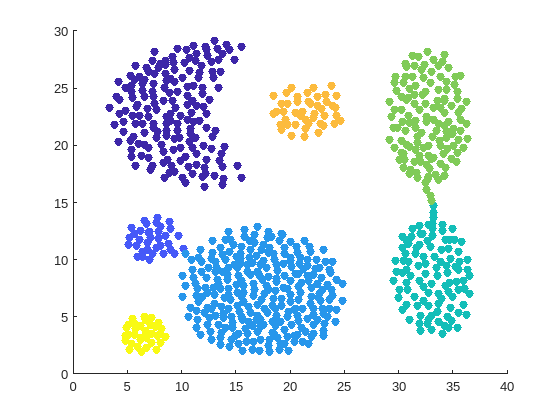

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9949

length(rnnDbscan.Clusters)

ans = 7

length(rnnDbscan.Outliers)

ans = 0

They were able to achieve a max ari of 0.998 and had 0 noise points.

### D31

#### original labels

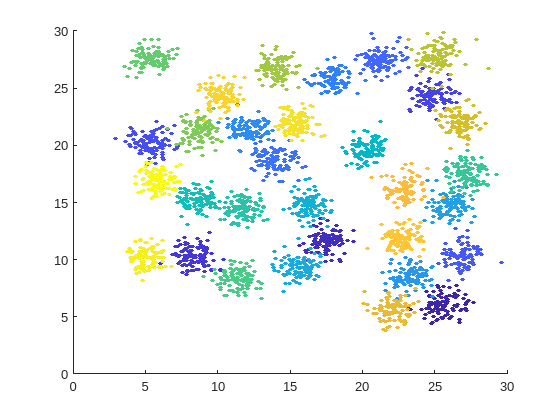

load([dataDir filesep 'D31.mat'])
scatter(data(:,1), data(:,2), 10, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

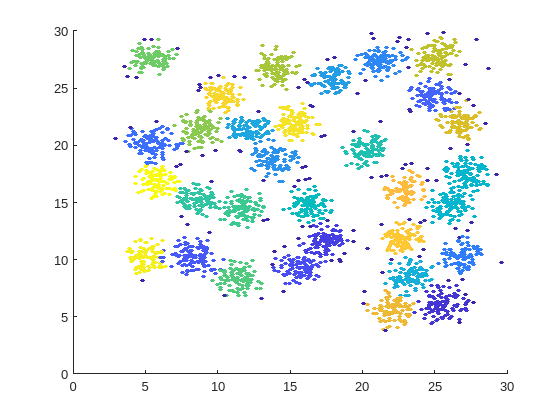

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 10, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.8665

length(rnnDbscan.Clusters)

ans = 30

length(rnnDbscan.Outliers)

ans = 120

They had an ari of 0.896, 31 clusters, and 167 noise points. I'm not really sure how to compare those results. The ari is similar enough. There are 31 true clusters in the dataset.

### Jain

#### original labels

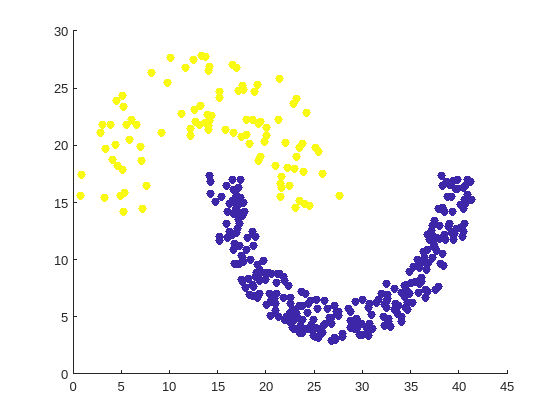

load([dataDir filesep 'jain.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

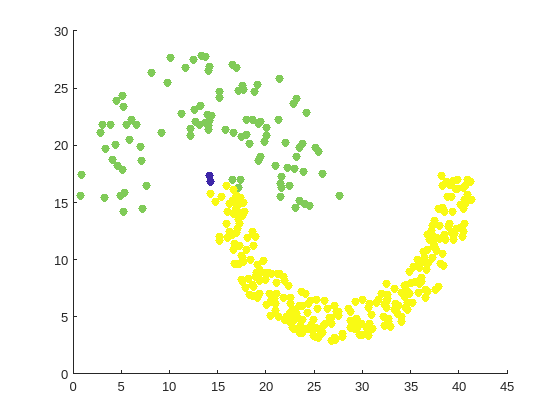

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9501

length(rnnDbscan.Clusters)

ans = 2

length(rnnDbscan.Outliers)

ans = 2

Their ari is 0.983, 2 clusters and 2 noise points. 

I think the order in which points are assigned to clusters is causing those 3 green points that clearly should be yellow to be misclassified. The green cluster is the first cluster that gets looked at, and the three misclassified points could belong to either cluster by the cluster definition given in the paper. When border points can belong to multiple clusters, I could "fix" the above behavior by assigning to the points to their closest cluster; that would ultimately be the best thing to do.

### R15

#### original labels

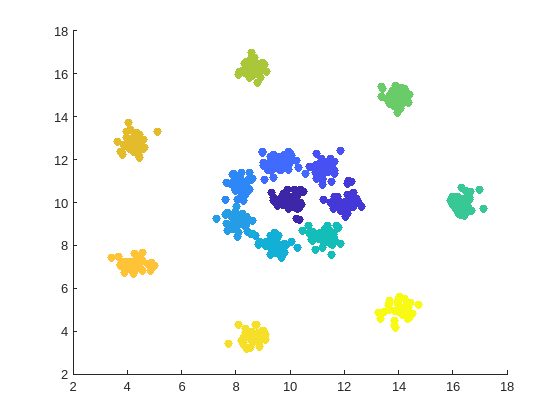

load([dataDir filesep 'R15.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

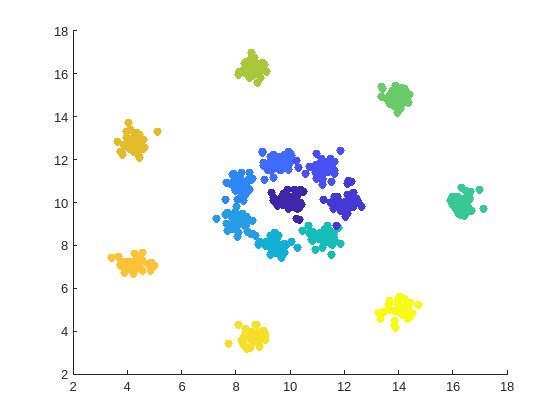

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9822

length(rnnDbscan.Clusters)

ans = 15

length(rnnDbscan.Outliers)

ans = 0

They report an ari of 0.984, 15 clusters and 3 noise points

### Flame

#### original labels

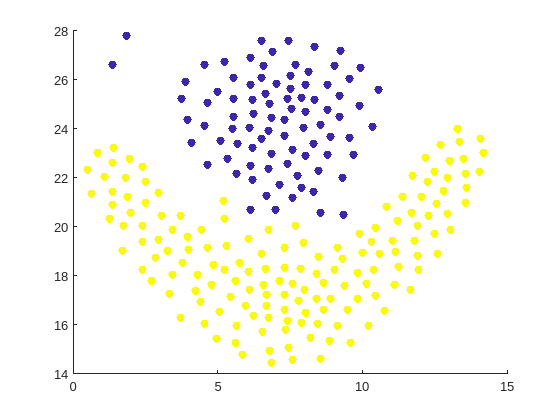

load([dataDir filesep 'flame.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

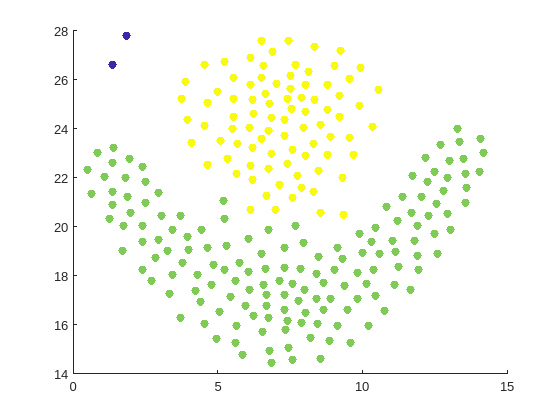

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9881

length(rnnDbscan.Clusters)

ans = 2

length(rnnDbscan.Outliers)

ans = 2

They report an ari of 0.971, 2 clusters and 2 noise points

### Pathbased

#### original labels

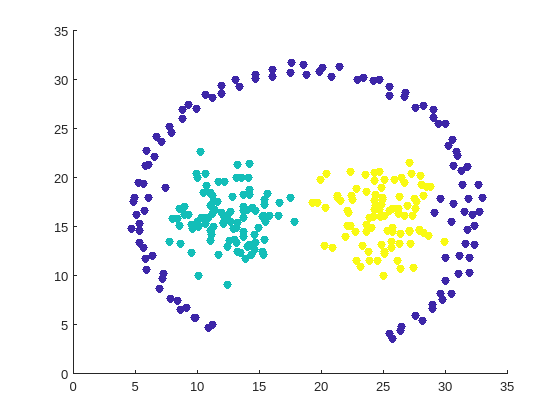

data = dlmread([dataDir filesep 'pathbased.txt']);
label = data(:,3);
data = data(:, 1:2);
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

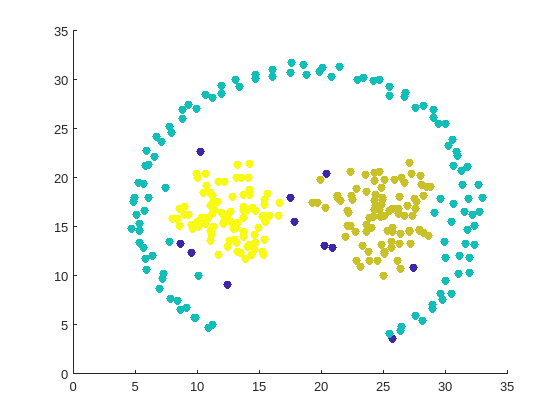

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9164

length(rnnDbscan.Clusters)

ans = 3

length(rnnDbscan.Outliers)

ans = 11

They report an ari of 0.917, 3 clusters and 11 noise points

### Spiral

#### original labels

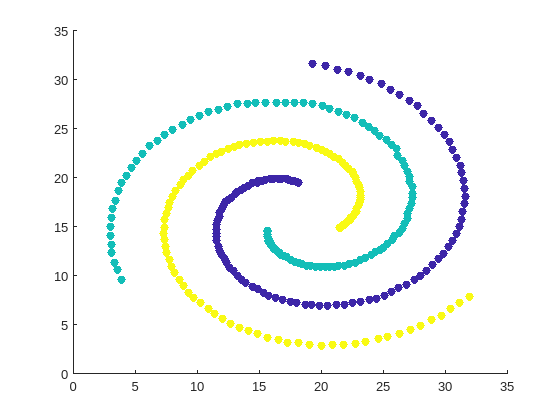

data = dlmread([dataDir filesep 'spiral.txt']);
label = data(:,3);
data = data(:, 1:2);
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

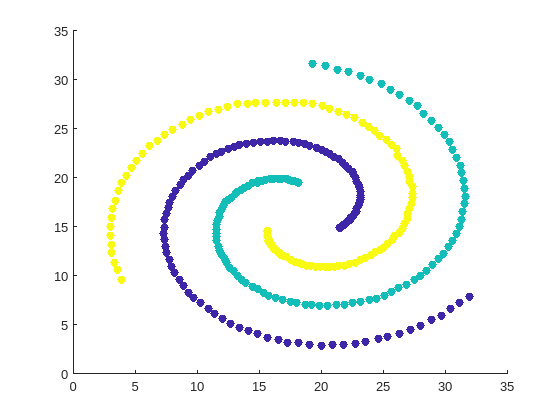

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 1

length(rnnDbscan.Clusters)

ans = 3

length(rnnDbscan.Outliers)

ans = 0

We both achieve perfect clustering on this dataset

The results on these synthetic datasets do not perfectly match the results reported in the paper, but they are generally close -- sometimes a little bit worse, and sometimes better.

They mention that non-core observations may be reachable from multiple clusters, and that such observations much be assigned to only one cluster in a hard clustering; their implementation "takes an arbitrary approach to the cluster assignment of such border observations that is dependent on observeration ordering". So it could be the case that I am assigning border observations in a different manner than they do, resulting in different results.

## Other synthetic datasets

These dataset were found online, but were not used in the RNN-DBSCAN paper

### 2-cluster

#### original labels

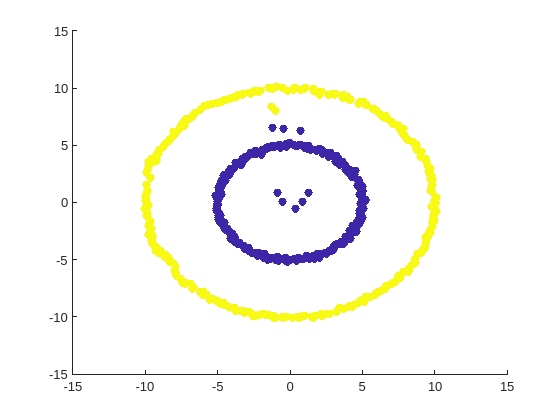

load([dataDir filesep '2-cluster.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

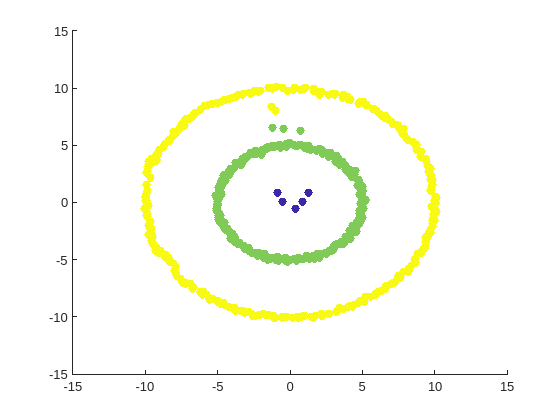

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9837

length(rnnDbscan.Clusters)

ans = 2

length(rnnDbscan.Outliers)

ans = 5

### Banana

#### original labels

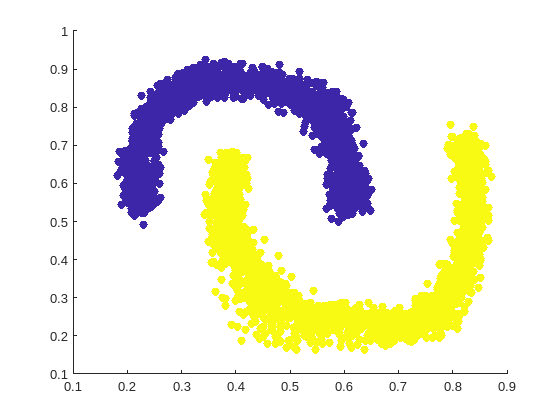

load([dataDir filesep 'banana.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

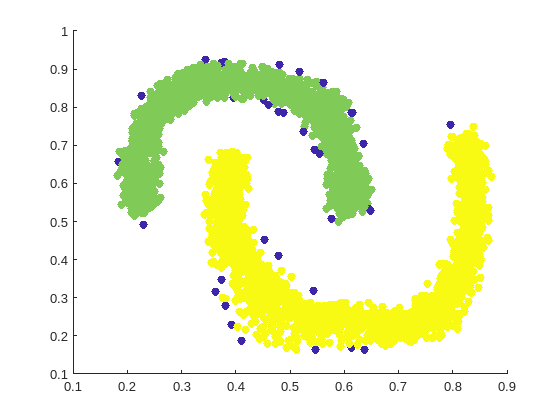

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9849

length(rnnDbscan.Clusters)

ans = 2

length(rnnDbscan.Outliers)

ans = 36

### Compound

#### original labels

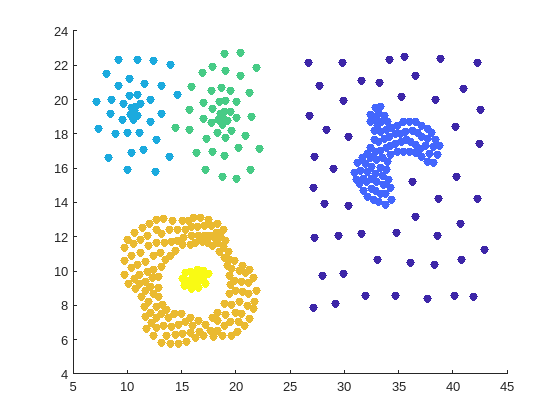

load([dataDir filesep 'compound.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

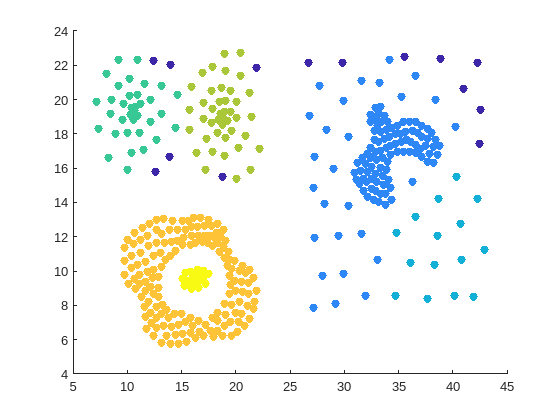

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.8821

length(rnnDbscan.Clusters)

ans = 6

length(rnnDbscan.Outliers)

ans = 14

### cure t2 rk

#### original labels

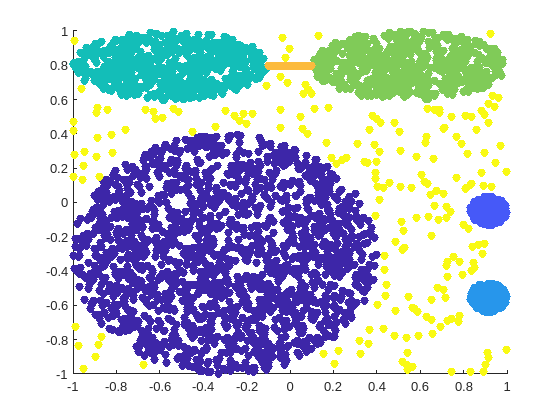

load([dataDir filesep 'cure-t2-4k.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

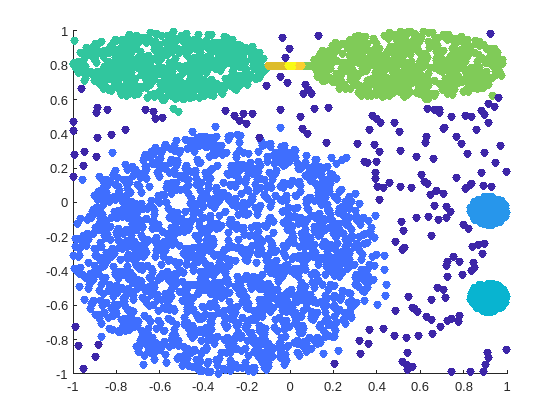

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9724

length(rnnDbscan.Clusters)

ans = 8

length(rnnDbscan.Outliers)

ans = 177

### Spiral Square

#### original labels

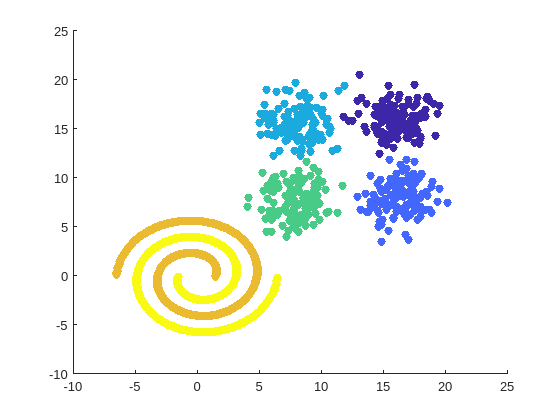

load([dataDir filesep 'spiralsquare.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

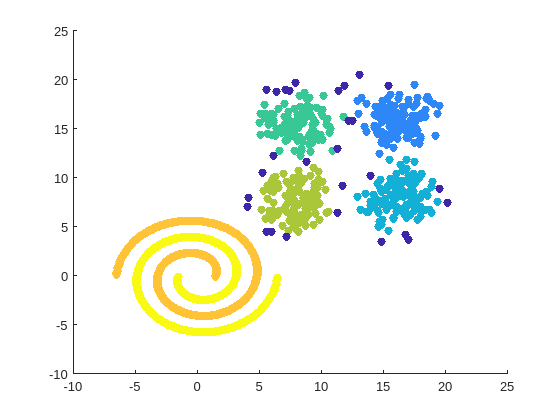

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9909

length(rnnDbscan.Clusters)

ans = 6

length(rnnDbscan.Outliers)

ans = 28

### Two Moon

#### original labels

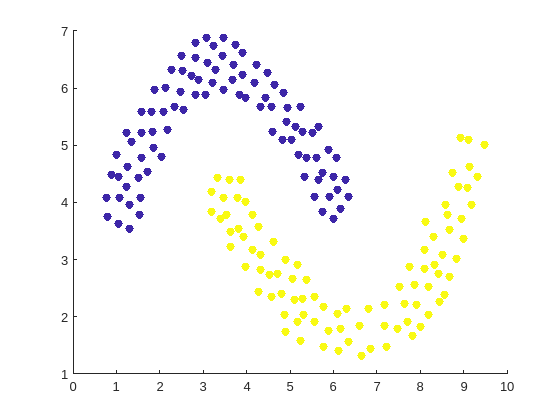

load([dataDir filesep 'twomoon.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 1

length(rnnDbscan.Clusters)

ans = 2

length(rnnDbscan.Outliers)

ans = 0

## Unbalanced datasets / datasets  with random noise

These dataset have cluster of unbalance size. These are a test of how w ell RNN-DBSCAN can detect small "outlier" clusters.

### Unbalance

This dataset has 3 clusters of size 2000 and 5 clusters of size 100. This should be a good test of the RNN-DBSCAN algorithm, as the algorithm is designed to detect small "outlier" clusters, which the size 100 clusters could be considered to fit that definition. This is from https://cs.joensuu.fi/sipu/datasets/, as several other datasets tested here have been.

#### original labels

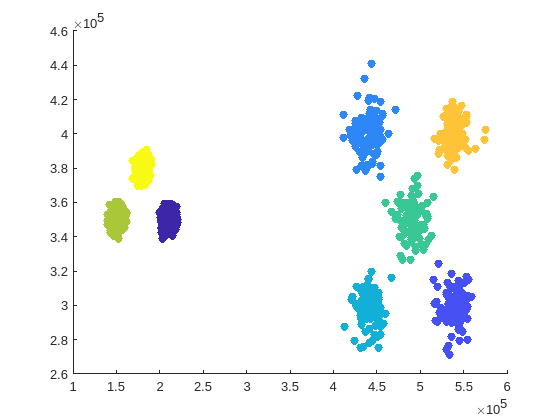

data = dlmread([dataDir filesep 'unbalance.txt']);
labels = importdata([dataDir filesep 'unbalance-gt.pa']);
scatter(data(:,1), data(:,2), 40, labels, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

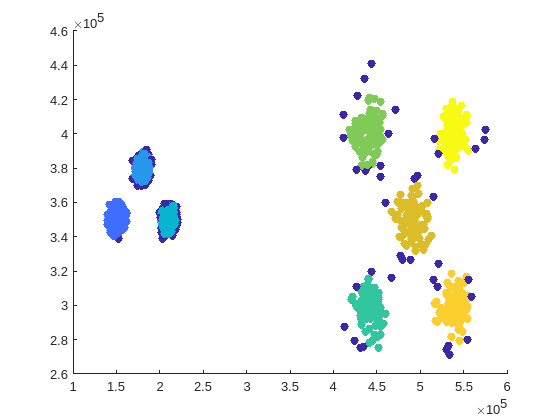

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9867

length(rnnDbscan.Clusters)

ans = 8

length(rnnDbscan.Outliers)

ans = 94

### 2D unbalanced blobs with noise

This dataset was created with scikit-learn's `make_blobs` function. The clusters have sizes of 20, 100, 500, and 1500.

#### original labels

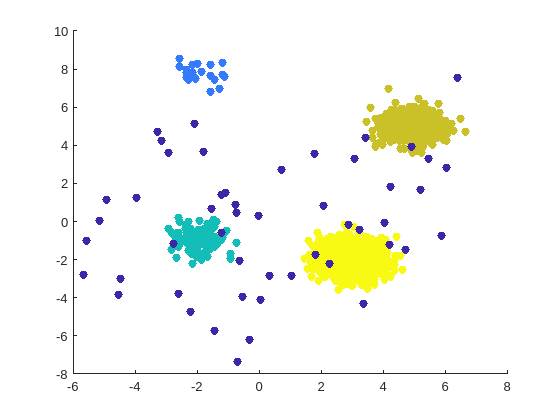

load([dataDir filesep 'unbalanced_blobs_2d_noise.mat'])
scatter(data(:,1), data(:,2), 40, labels, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(labels, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

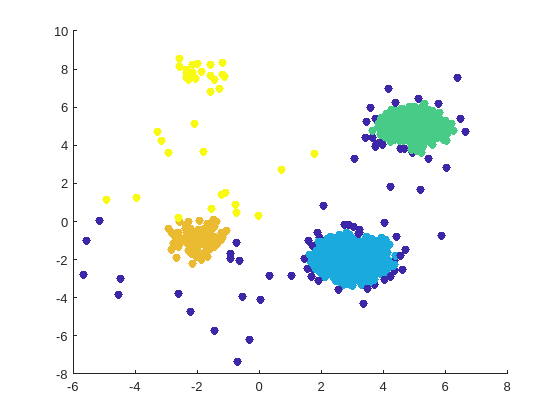

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9545

length(rnnDbscan.Clusters)

ans = 4

length(rnnDbscan.Outliers)

ans = 74

### 20D unbalanced blobs with noise

This dataset was created with scikit-learn's `make_classification` function. The proportions of the cluster sizes are 0.02, 0.12, 0.5, and 0.5, split across 1000 samples. 50 random noise points were added.

The datset here has 2 informative featuers and 18 uninformative features.

#### original labels

load([dataDir filesep 'unbalanced_blobs_2d_noise.mat'])
scatter(data(:,1), data(:,2), 40, labels, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(labels, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9545

length(rnnDbscan.Clusters)

ans = 4

length(rnnDbscan.Outliers)

ans = 74

### Moons with noise

Two moons with noise were generated by scikit-learn's `make_moons` method. The moons have 500 sapmle total, with a noise standard deviation of 0.1. 20 random noise points were added.

#### original labels

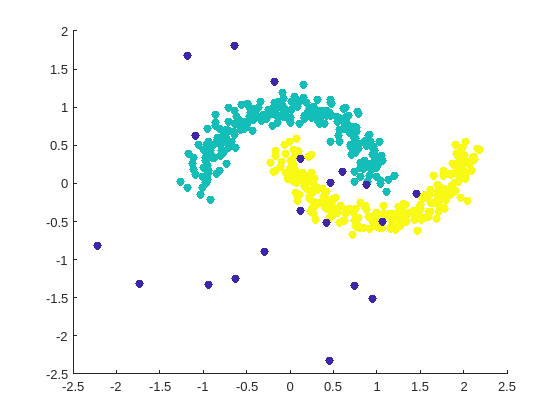

load([dataDir filesep 'moons_with_noise.mat'])
scatter(data(:,1), data(:,2), 40, labels, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(labels, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

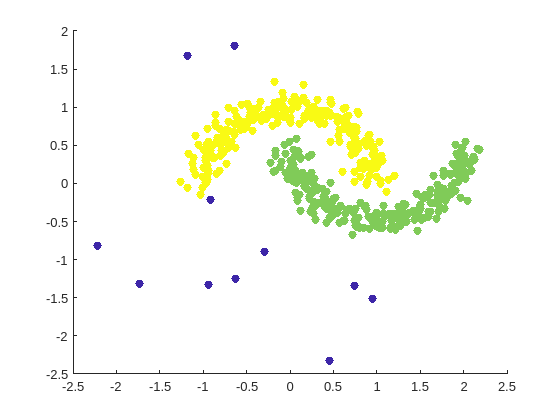

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9572

length(rnnDbscan.Clusters)

ans = 2

length(rnnDbscan.Outliers)

ans = 11

### Grid

3 grids of different densities and 40 points of random noise. The grids are separated by the inter-point separation of the sparset grid.

#### original labels

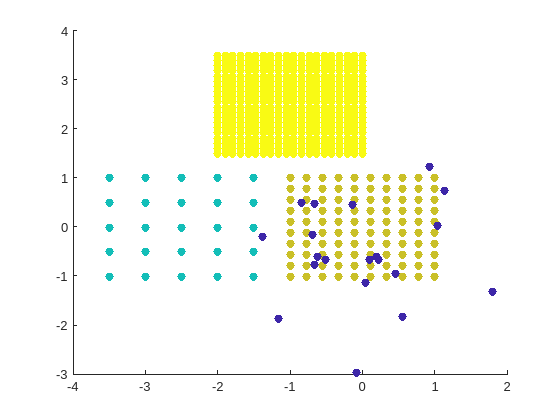

load([dataDir filesep 'multiple_grids_noise.mat'])
scatter(data(:,1), data(:,2), 40, labels, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(labels, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

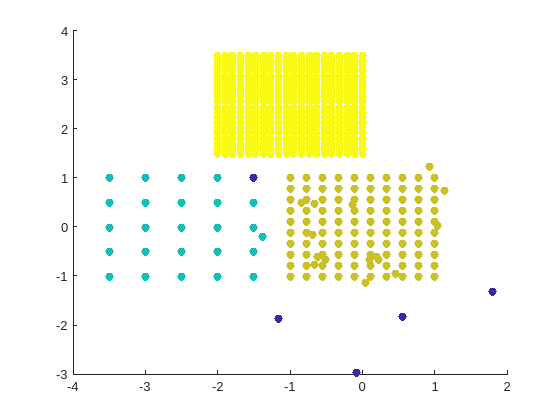

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9774

length(rnnDbscan.Clusters)

ans = 3

length(rnnDbscan.Outliers)

ans = 5